clear all;
close all;

**Giordano Dylan - Martelet Curtis                            L3 EEA_Gr TP1**

# Rapport TDP9: Convertisseurs continu-continu Forward

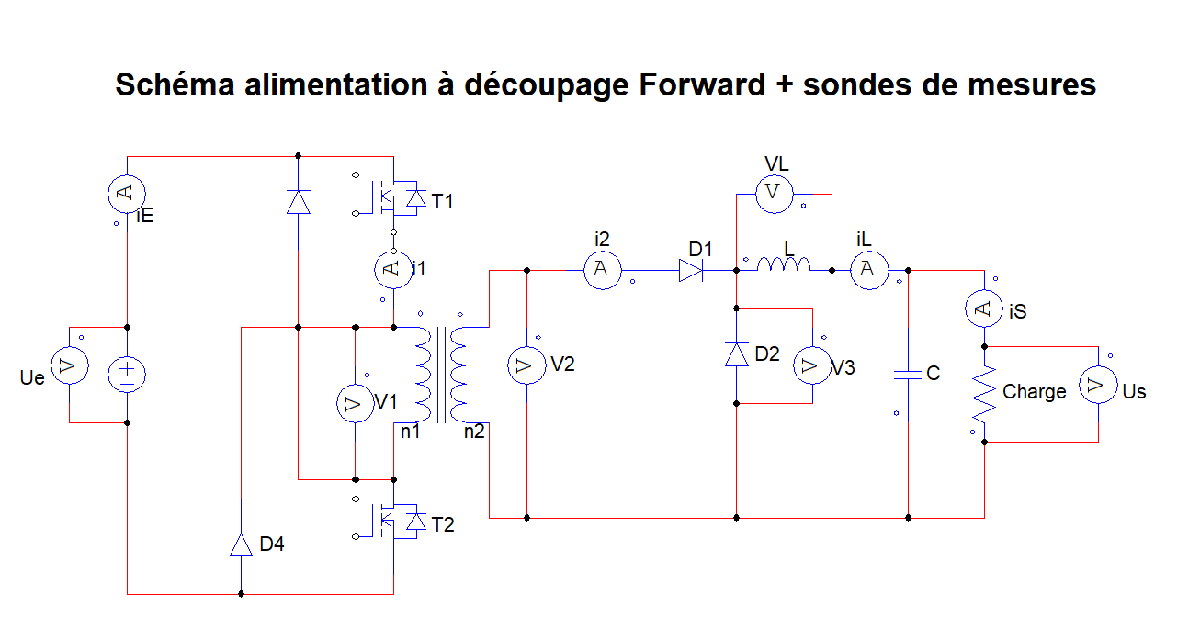

## Partie 4: Travail demandé

### 2. Etude du fonctionnement en régime nominal

Ve=60V et Ie = 1.38A. 

Vs=42.8V et IL=1.71A.

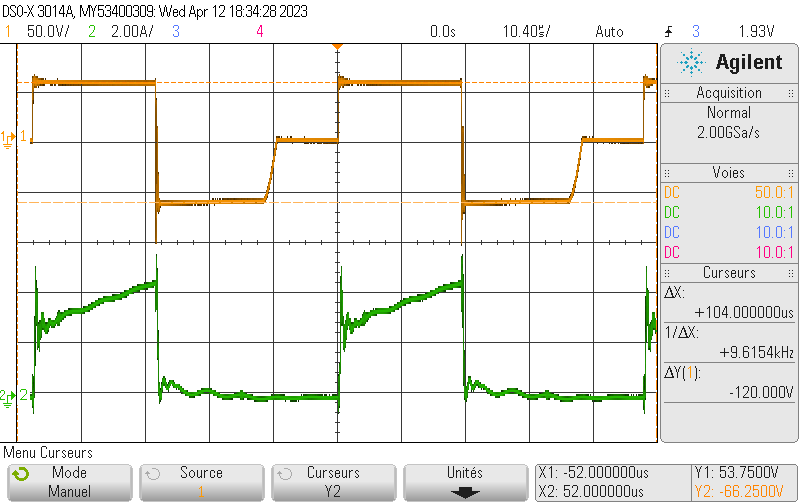

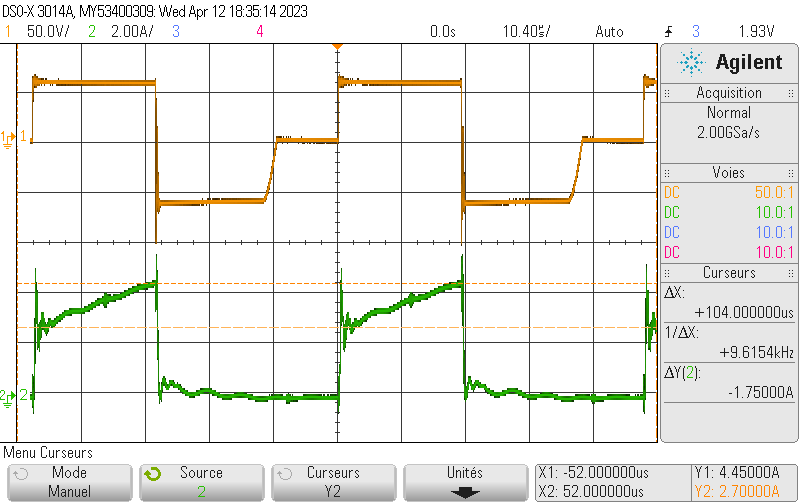

#### Orange $\Longrightarrow \;v_1 \left(t\right)$; Vert $\Longrightarrow \;i_1 \left(t\right)$

Quand on observe le primaire, on peut clairement voir les trois "moments" qui se déroulent dans le transformateur:

- de 0 à αT, V1=53.7V

- de αT à 2αT, V1= -66.25V

- de 2αT à T, V1=0V.

Comme durant le TP, on mesure une tension moyenne nulle. On peut donc conclure que le relevé est conforme à la théorie.

On peut observer que le courant I1 est crooissant de 0 à αT puisque les transistors sont fermés et que la tension est positive. De αT à T, le courant est nul (les transistors sont ouverts).

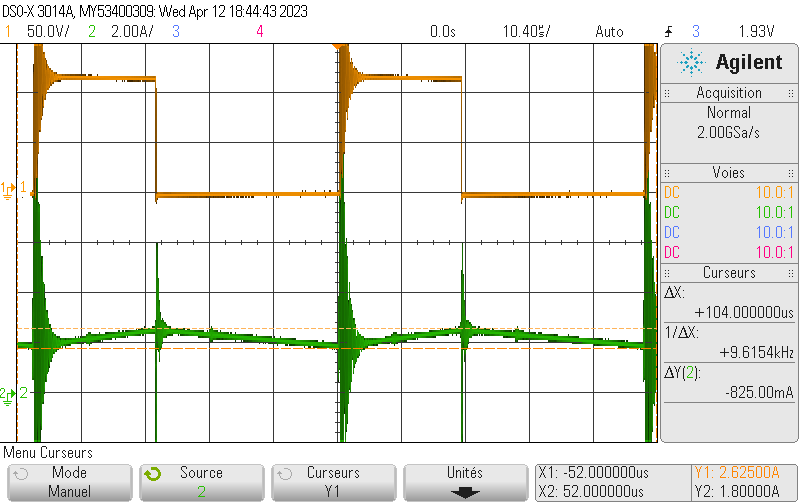

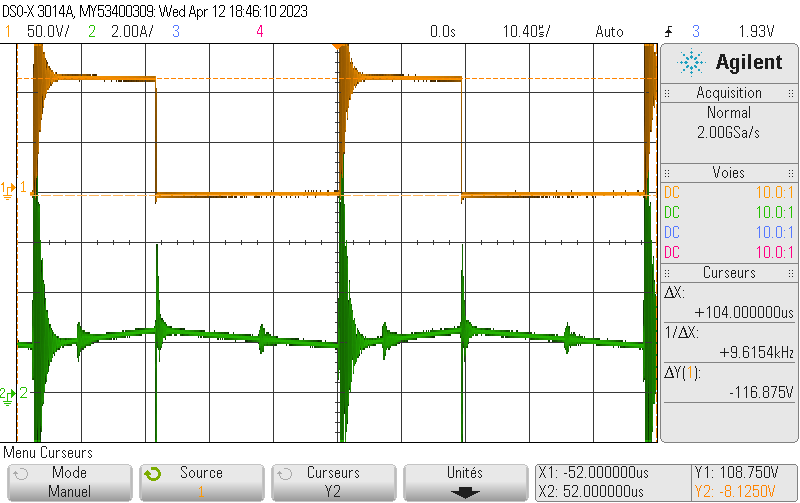

#### Orange $\Longrightarrow \;v_2 \left(t\right)$; Vert $\Longrightarrow \;i_L \left(t\right)$

De 0 à αT, on peut observer que V2=mV1 avec m=2. Le courant iL est croissant.

Quand les transistors sont bloqués, alors la tension V2 devient nulle. Le courant iL se décharge dans la charge, donc le courant est décroissant.

#### 
$$\Delta i_L =780\textrm{mA}$$


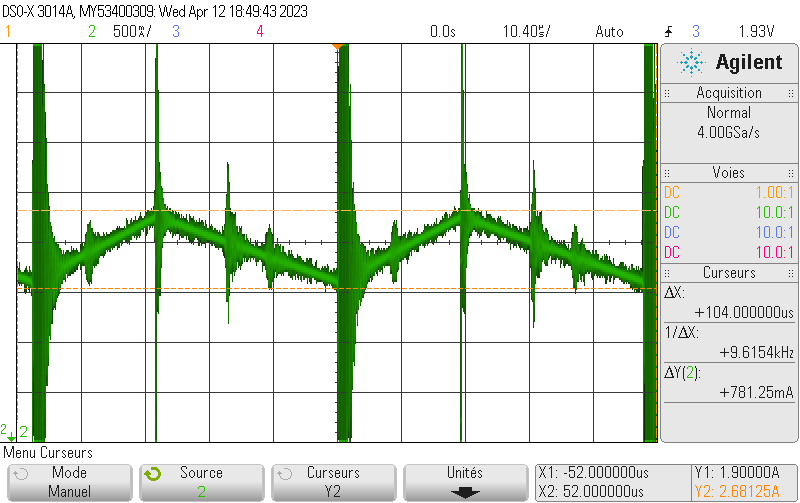

#### Vert $\Longrightarrow \;i_L \left(t\right)$

#### 
$$\Delta v_s =100\textrm{mA}$$


### 3. Etude de l'induction dans me circuit magnétique

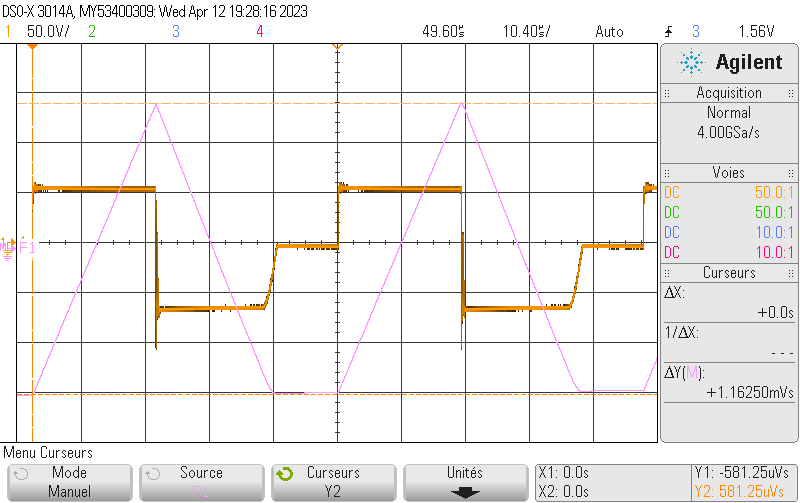

#### Orange $\Longrightarrow \;v_1 \left(t\right)$; Rose $\Longrightarrow \textrm{intégrale}\;\textrm{de}\;v_1 \left(t\right)$

L'allure de la courbe est similaire à celle théorique.

On peut voir sur l'intégrale de V1 (ce qui correspond à B sans le produit de $\frac{1}{n_1 \times S_{\textrm{FER}} }$) qu'une partie de la courbe est plate, c'est à dire qu'il n'y a plus aucune évolution de la magnétisation en fonction du temps. C'est provoqué par la : on a donc une démagnétisation complète.

On calcul $B_{\textrm{MAX}}$.

$S_{\textrm{FER}} =\pi \times r^2 =173\textrm{mm²}$ & $n_1 =35$


$$B_{\textrm{MAX}} =\frac{1\ldotp 16{\times 10}^{-3} }{n_1 \times S_{\textrm{FER}} }=\frac{1\ldotp 16{\times 10}^{-3} }{35\times 173{\times 10}^{-6} }=0\ldotp 1916\;T$$



$$V_e =60V\;\&\;I_e =1\ldotp 38A\longrightarrow P_e =60\times 1\ldotp 38=82\ldotp 8W$$
           
$$V_s =42\ldotp 8V\;\&\;I_L =1\ldotp 71A\longrightarrow P_S =42\ldotp 8\times 1\ldotp 71=73\ldotp 19W$$


$\eta =\frac{P_S }{P_e }=\frac{73\ldotp 19}{82\ldotp 8}=0\ldotp 884$. Le rendement de ce convertisseur forward est de 88.4%.

### 4. Variation de la tension de sortie

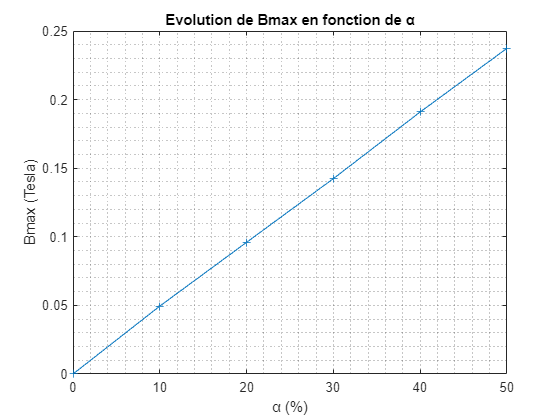

n1=35;S=173e-6;
alpha = [0 0.1 0.2 0.3 0.4 0.5]*100;
B = [0 299.8e-6 581.25e-6 862.5e-6 1.1565e-3 1.4375e-3]/(n1*S);

plot(alpha,B,'+-')
title("Evolution de Bmax en fonction de α")
xlabel('α (%)');ylabel('Bmax (Tesla)')
grid minor

$B_{\textrm{MAX}}$ est linéaire en fonction du rapport cyclique.

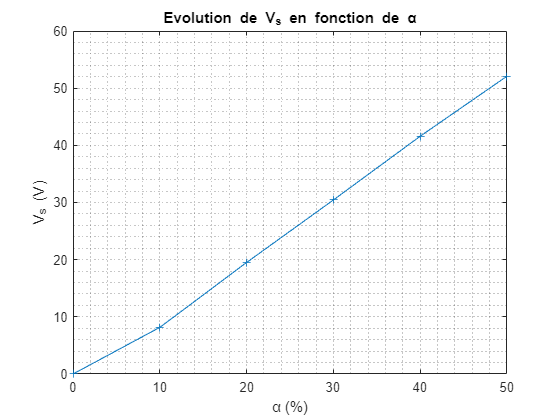

Vs = [0 8.16 19.51 30.45 41.6 52.1];
plot(alpha,Vs,'+-')
title("Evolution de V_s en fonction de α")
xlabel('α (%)');ylabel('V_s (V)')
grid minor

La courbe est 

Tout comme la courbe précédente, on peut observer que $V_S$ est linéaire en fonction du rapport cyclique, ce qui est normal puisque $V_S =\alpha \frac{n_2 }{n_1 }\times V_e$. Or, on sait que $B_{\textrm{MAX}}$ est proportionnel à la tension $V_S$.

### 5. Rendement

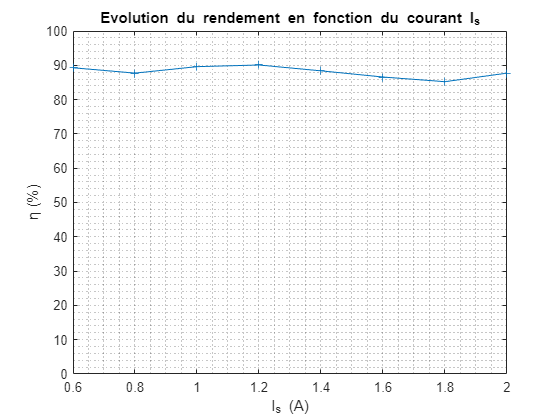

Ve = 60;
Ie = [1.9 1.76 1.54 1.32 1.11 0.93 0.76 0.56];
Vs = 50;
Is = [2 1.8 1.6 1.4 1.2 1 0.8 0.6];

plot(Is,Vs.*Is./(Ve.*Ie)*100,'+-')
title("Evolution du rendement en fonction du courant I_s")
xlabel('I_s (A)');ylabel('η (%)')
grid minor
ylim([0 100])

On peut observer grâce à cette courbe que le rendement entre le primaire et le secondaire du convertisseur reste stable qu'importe la tension en sortie. Plus $I_S$ est petit, plus le rapport cyclique doit l'être également.